## A Frequency Adaptive Phase Shift Modulation Control Based LLC Series Resonant Converter for Wide Input Voltage Applications

目前只写了有关FAPSM的参数设计

Written by Eva Ke

## 参数设计 PARAMETER DESIGN

### 应用背景

#### 拓扑选择

对于一些特殊的拓扑，相关参数与调制方式也有关。

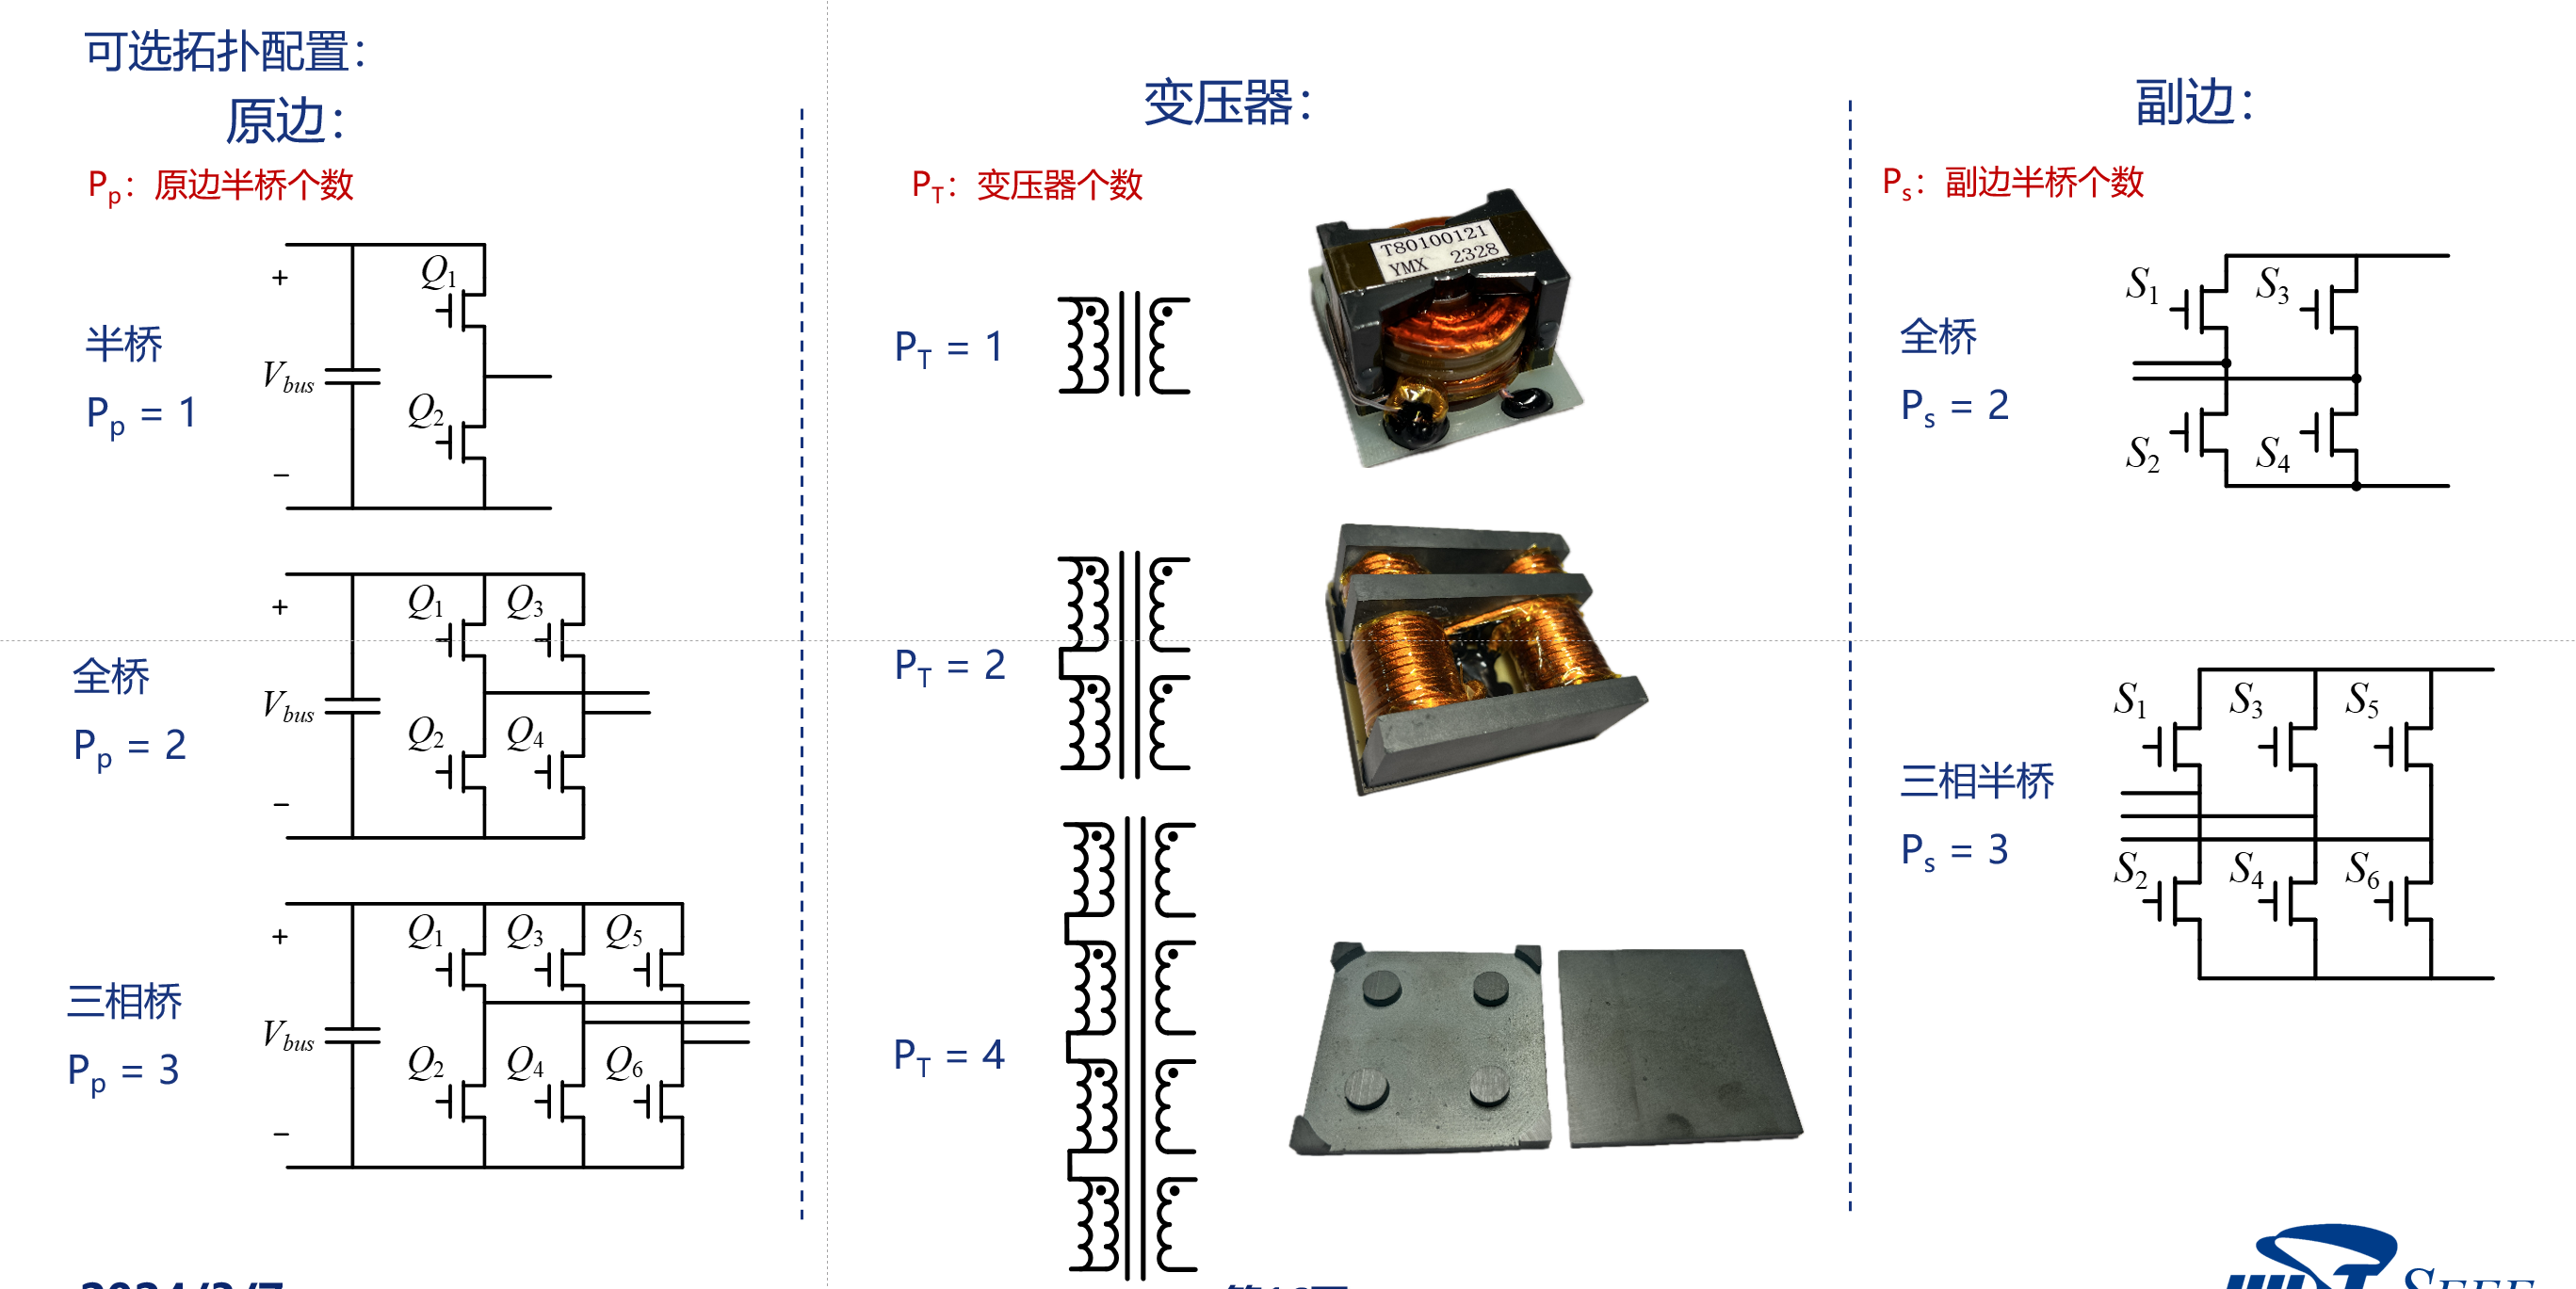

Pp=2;               %原边半桥个数，默认全桥Pp=2
PT=1;               %变压器个数，默认为1
Ps=2;               %副边半桥个数，默认全桥Ps=2

#### 电路参数

GainMode="浮动母线";            %增益模式
                                          %浮动母线代表着增益范围为(Vomax/Vinmax,Vomin/Vinmin)
                                          %全增益代表着增益范围为(Vomax/Vinmin,Vomin/Vinmax)

Vp_min = 400;            %一次侧最小电压，输入侧设置为谐振腔所在侧
Vp_max = 400;            %一次侧最大电压
Vs_min = 36;            %二次侧最小电压
Vs_max = 60;            %二次侧最大电压
Vs_rated=48;            %二次侧额定电压

增益计算

if GainMode=="浮动母线"
    Vs2Vp = sort([Vs_max/Vp_max,Vs_min/Vp_min])
elseif GainMode=="全增益"
    Vs2Vp = sort([Vs_min/Vp_max,Vs_max/Vp_min])
end

Vs2Vp =     0.0900    0.1500


Po_rated = 1000;          %额定功率
LightLoad =0.5;    %轻载功率比例
HeavyLoad =1.3;    %过载功率比例，目前只能设置为1

#### **调制策略**

频率适应移相调制 FAPSM ：*A Frequency Adaptive Phase Shift Modulation Control Based LLC Series Resonant Converter for Wide Input Voltage Applications*

ModulationMode = "FAPSM";    %调制策略
                                          %目前只做了FAPSM，所以没有写判断，如果后面要加新的调制策略需要加方案

**开关频率范围**

Fs_min = 100000;            %开关频率极限最小值
Fs_max = 500000;            %开关频率极限最大值
Fs_best = 300000;           %开关频率最优值 300e3,使得RatedPower下在该处

### FAPFM

#### 通过ZVS确定品质因数

由ZVS条件（任意移相角下输入阻抗都必须为感性）得到开关频率和品质因数的关系


$$F-\frac{1}{F}>\frac{1}{2Q}$$


品质因数Q的选择决定了开关频率的选择。

Q越大，谐振腔存储的功率越多，对谐振腔元件的要求也越大。

Q越小，轻载下的开关频率越大。

下式展示了不同的额定品质因数与开关频率范围的关系。用户需要合理设计额定品质因数，使得开关频率范围合理。

Q_max = 2.485;
Q_rated = Q_max/HeavyLoad;
Q = [Q_rated*LightLoad*(min(Vs2Vp)/max(Vs2Vp))^2,Q_rated*(min(Vs2Vp)/max(Vs2Vp))^2,Q_rated*(min(Vs2Vp)/max(Vs2Vp))^2*HeavyLoad,Q_rated*LightLoad,Q_rated,Q_rated*HeavyLoad]

Q =     0.3441    0.6882    0.8946    0.9558    1.9115    2.4850


Q=[0.7711 1.5421 2.0048 ]%反向

Q =     0.7711    1.5421    2.0048


F = 1./(4*Q)+sqrt(1./(Q.^2)/16+1)

F =     1.3755    1.1752    1.1324


#### 通过限制无功功率与有功功率之比，限制无功功率范围，进而确定可能合适的增益和确认变压器变比

由无功功率和有功功率之比的范围，可以确认可行的增益范围。要求是**最大增益**下能实现**全负载范围**的无功环流比例都小于设定要求。

二次侧电流（正向功率为正）超前于二次侧电压的角度为Theta。


$$\frac{P_r }{P_o }=\frac{1}{2\pi }\tan \Theta -\frac{\Theta }{2\pi }$$


ReacPowerEta = 0.2 ;
syms x
func =(tan(x)-x)/2/pi - ReacPowerEta;
Theta_max = vpasolve(func,x,1);
fprintf("二次侧电流（正向功率为正）超前于二次侧电压的角度最大可为%.2f度",rad2deg(Theta_max));

二次侧电流（正向功率为正）超前于二次侧电压的角度最大可为67.70度

二次侧电流（正向功率为正）超前于二次侧电压的角度与移相角Psi的关系：


$$\Theta =\tan^{-1} \left(\frac{F-\frac{1}{F}+\frac{F}{K}}{Q\left(F-\frac{1}{F}\right)*\frac{F}{K}}-\cot \Psi \right)=\tan^{-1} \left(\frac{\frac{1}{2Q}+\frac{F}{K}}{\frac{1}{2}*\frac{F}{K}}-\cot \Psi \right)=\tan^{-1} \left(2K\left(1-\frac{1}{F^2 }+\frac{1}{K}\right)-\cot \Psi \right)$$


最大的F（品质因数最小）和最大的Psi导致最大的Theta。即最大增益下要让轻载也能满足Theta范围。

K_temp=0.21;
Psi_max =acot(2*K_temp*(1-1/(max(F)^2)+1/K_temp) - tan(Theta_max))

$$Psi\_max = -1.4442242901845233911912012050344$$

G_max = FAPSM_Gain(K_temp,max(F),min(Q),Psi_max);
fprintf("当Lr/Lm暂时设置为%.2f，移相角最大可为%.2f度,此时可达的最大增益为%.3f,如果增益超出该范围则使得轻载下无功功率过大超出有功功率的%.3f。",K_temp,rad2deg(Psi_max),G_max,ReacPowerEta);

当Lr/Lm暂时设置为0.21，移相角最大可为-82.75度,此时可达的最大增益为1.984,如果增益超出该范围则使得轻载下无功功率过大超出有功功率的0.200。

由用户设置实际的最大增益。建议首先拖动K_temp找到合适的最大增益区域，以免设计的最大增益不合适。Mmax_temp与G_max接近时最终设计的K接近。

变压器变比 n_temp，最大增益Mmax和K息息相关，建议通过上面部分估算M的可行区间。


$$M_{\max } =\max \left(n\frac{P_s V_s }{{P_p P_T V}_p }\right)$$


M_max_temp = 1.5;
M_temp = [M_max_temp*(min(Vs2Vp)/max(Vs2Vp)),M_max_temp]

M_temp =     0.9000    1.5000


n_temp =  M_max_temp/max(Vs2Vp)*Pp*PT/Ps

n_temp = 10

实际选择的n尽量接近n_temp，但是又要求易于实现，一般需要使得其为整数除以整数，如2:1，4:1，15:4。

n = 10;
M = n*Ps/Pp/PT*Vs2Vp

M =     0.9000    1.5000


**由副边ZVS确定电感比K**


$$A=\frac{Q\left(F^2 -1\right)}{F}=\frac{1}{2}$$



$$K>|\frac{A\sqrt{\frac{1}{A^2 G^2 }-1}-1}{1-\frac{1}{F^2 }}|$$


最小的F和最小的G下K存在极限值。此时的Pr/Po为0(临界ZVS)。

A=1/2;
K_min=abs((A*sqrt(1/(A^2*min(M)^2)-1)-1)/(1-1/min(F)^2))

K_min = 0.0426

K越大，Lr/Lm越大，Lm越小，副边越容易ZVS，但Pr越大，引起较大的环流损耗。

K = 0.043;%比Kmin大，但不要大太多


#### 谐振频率选择


$$F\left(P_{\mathrm{rated}} \right)*F_r =F_{s\;\mathrm{best}}$$


Fr=Fs_best/F(5)

Fr = 2.6332e+05

wr=2*pi*Fr;

#### 谐振腔参数计算


$$Z=\frac{8n^2 V_o^2 Q}{\pi^2 P_o }$$


Qmax>Q(Pomax,Vomin)

Qmin<Q(Pomin,Vomax)

Z=[min(Q)*8*n^2*Vs_max^2/(pi^2*Po_rated*LightLoad),max(Q)*8*n^2*Vs_min^2/(pi^2*Po_rated*HeavyLoad)]

Z =   200.8067  200.8067


Z=316

%Z=262


$$L_r =\frac{Z}{\omega_r }$$



$$C_r =\frac{1}{Z\omega_r }$$



$$L_M =\frac{L_r }{K}$$


Z=mean(Z)

Z = 200.8067

Lr=Z/wr

Lr = 1.2137e-04

Cr=1/(Z*wr)

Cr = 3.0099e-09

LM=Lr/K

LM = 0.0028

n

n = 10

F

F =     1.9627    1.4272    1.3178    1.2952    1.1393    1.1057


Q

Q =     0.3441    0.6882    0.8946    0.9558    1.9115    2.4850


%G=[,Vs2Vp(1)/n]
syms Psi
for i = (1:1:6)
    f=F(i);
    q=Q(i);
    if i<=3
        eqn = Vs2Vp(2)*n==1/sqrt( ((1+K-K/f^2)- (q*(f^2-1)/f*( (f*K+f-K/f)/(q*(f^2-1)) -cot(Psi) )))^2+ (q*(f^2-1)/f)^2);
        psi=vpasolve(eqn,1);
    else
        eqn = Vs2Vp(1)*n==1/sqrt( ((1+K-K/f^2)- (q*(f^2-1)/f*( (f*K+f-K/f)/(q*(f^2-1)) -cot(Psi) )))^2+ (q*(f^2-1)/f)^2);
        psi=vpasolve(eqn,1);
    end
    theta=atan((f*K+f-K/f)/(q*(f^2-1))-cot(psi));
    pr2po=1/2/pi*tan(theta)-theta/2/pi;
    fprintf("F=%.4f,Q=%0.4f,Psi=%.2f度,Theta=%.2f度，Pr/Po=%.3f\n",f,q,rad2deg(psi),rad2deg(theta),pr2po);
end

F=1.9627,Q=0.3441,Psi=48.59度,Theta=49.76度，Pr/Po=0.050
F=1.4272,Q=0.6882,Psi=48.59度,Theta=49.28度，Pr/Po=0.048
F=1.3178,Q=0.8946,Psi=48.59度,Theta=49.10度，Pr/Po=0.047
F=1.2952,Q=0.9558,Psi=26.74度,Theta=2.88度，Pr/Po=0.000
F=1.1393,Q=1.9115,Psi=26.74度,Theta=2.02度，Pr/Po=0.000
F=1.1057,Q=2.4850,Psi=26.74度,Theta=1.78度，Pr/Po=0.000


Fs = F*(1/sqrt(Lr*Cr)/2/pi)

Fs = 1.0e+05 *

    5.1681    3.7582    3.4699    3.4105    3.0000    2.9114
